1) A partir das funções de transferência H(s) obtidas no trabalho "[Projeto de Filtros de Tempo Contínuo e Ativos](https://moodle.utfpr.edu.br/mod/assign/view.php?id=711353)", discretizar os que seguem abaixo usando o método da invariância ao  impulso e da transformada bilinear. Considere a frequência de amostragem de 40 kHz.

Fs = 40e3;
Ts = 1/Fs;
syms z
s = tf('s');

a) Passa-baixas de segunda ordem. Detalhar a aplicação dos métodos de  discretização. Ao final, comparar os resultados com os obtidos com os  comandos c2d(num, den, ’impulse’) e c2d(num, den, ’tustin’) do  Matlab/Python. 

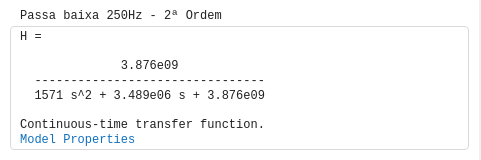

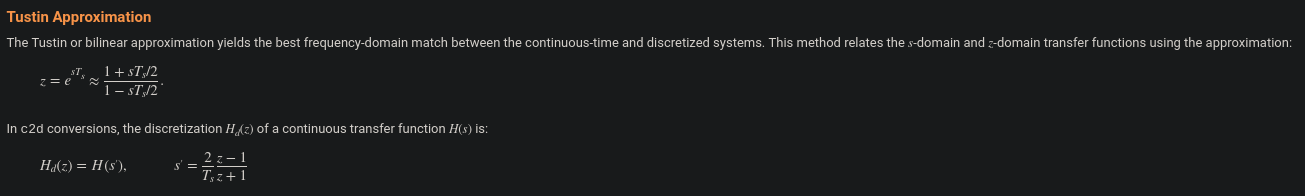

H = 3.876e9 / (1571*s^2 + 3.489e6*s + 3.876e9)


H =
 
              3.876e09
  --------------------------------
  1571 s^2 + 3.489e06 s + 3.876e09
 
Continuous-time transfer function.
Model Properties



disp("================== Invariância ao Impulso ==================")

================== Invariância ao Impulso ==================


t_ii = 0:Ts:0.5;
[y_ii, ~] = impulse(H, t_ii); 
[num, den] = prony(y_ii, 1, 2);

Hd_ii = tf(num, den, Ts)


Hd_ii =
 
          59.98
  ---------------------
  z^2 - 1.944 z + 0.946
 
Sample time: 2.5e-05 seconds
Discrete-time transfer function.
Model Properties


Hd_ii_c2d = c2d(H, Ts, 'impulse')


Hd_ii_c2d =
 
        0.0015 z
  ---------------------
  z^2 - 1.944 z + 0.946
 
Sample time: 2.5e-05 seconds
Discrete-time transfer function.
Model Properties


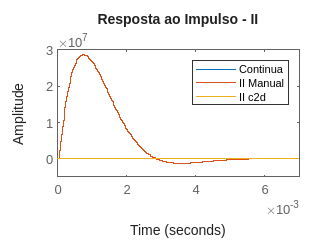


figure;
impulse(H, Hd_ii, Hd_ii_c2d);
legend('Continua', 'II Manual', 'II c2d');
title('Resposta ao Impulso - II');

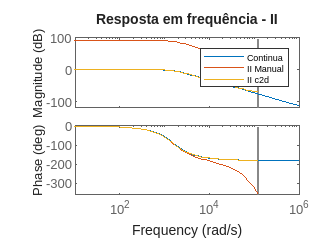


figure;
bode(H, Hd_ii, Hd_ii_c2d);
legend('Continua', 'II Manual', 'II c2d');
title('Resposta em frequência - II');


% Numerador do meu II esta dando diferente do c2d, creio que fiz de maneira errada

disp("================== Tustin ==================")

================== Tustin ==================


s_tustin = (2/Ts)*(z - 1)/(z + 1);

H_tustin_aux = 3.876e9 / (1571*s_tustin^2 + 3.489e6*s_tustin + 3.876e9);
[num, den] = numden(H_tustin_aux);
num_z = sym2poly(num);
den_z = sym2poly(den);

Hd_tustin = tf(num_z, den_z, Ts)


Hd_tustin =
 
         969 z^2 + 1938 z + 969
  ------------------------------------
  2.584e06 z^2 - 5.025e06 z + 2.445e06
 
Sample time: 2.5e-05 seconds
Discrete-time transfer function.
Model Properties


Hd_tustin_c2d = c2d(H,Ts,'tustin')


Hd_tustin_c2d =
 
  0.0003749 z^2 + 0.0007499 z + 0.0003749
  ---------------------------------------
           z^2 - 1.944 z + 0.946
 
Sample time: 2.5e-05 seconds
Discrete-time transfer function.
Model Properties


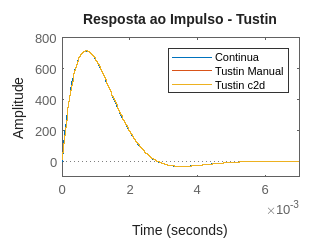


% Diferença aparente entre elas é que em Hd_tustin_c2d os coeficientes foram
% divididos por 2.584e06

figure;
impulse(H, Hd_tustin, Hd_tustin_c2d);
legend('Continua', 'Tustin Manual', 'Tustin c2d');
title('Resposta ao Impulso - Tustin');


figure;
bode(H, Hd_tustin, Hd_tustin_c2d);
legend('Continua', 'Tustin Manual', 'Tustin c2d');
title('Resposta em frequência - Tustin');

disp("================== Impl. Tustin ==================")

================== Impl. Tustin ==================


b = num_z;
a = den_z;

% normalizar se a(1) ~= 1
if a(1) ~= 1
    b = b / a(1);
    a = a / a(1);
end


frequencias = [25, 250, 2500];  
duracao = 0.05;                 
t = 0:Ts:duracao;

figure;
for i = 1:length(frequencias)
    f = frequencias(i);
    x = sin(2*pi*f*t);   
    y = zeros(size(x));
    
    for n = 3:length(x)
        y(n) = b(1)*x(n) + b(2)*x(n-1) + b(3)*x(n-2) - a(2)*y(n-1) - a(3)*y(n-2);
    end

    subplot(length(frequencias), 1, i);
    plot(t, x, 'b', 'DisplayName', 'Entrada'); hold on;
    plot(t, y, 'r', 'DisplayName', 'Saída (Filtro Tustin)');
    title(['Resposta para Senoidal de ', num2str(f), ' Hz']);
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    legend;
end

b) Passa-altas de segunda ordem.

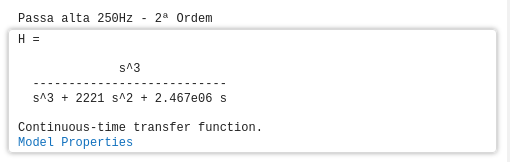

H = s^2 / (s^2 + 2221*s + 2.467e6)


H =
 
            s^2
  -----------------------
  s^2 + 2221 s + 2.467e06
 
Continuous-time transfer function.
Model Properties



H_tustin = c2d(H, Ts, 'tustin')


H_tustin =
 
  0.9726 z^2 - 1.945 z + 0.9726
  -----------------------------
      z^2 - 1.944 z + 0.946
 
Sample time: 2.5e-05 seconds
Discrete-time transfer function.
Model Properties


figure;
bode(H, H_tustin);
legend('Continua', 'Tustin c2d');
title('Resposta em frequência');
[num, den] = tfdata(H_tustin, 'v');

b = num;
a = den;

% normalizar se a(1) ~= 1
if a(1) ~= 1
    b = b / a(1);
    a = a / a(1);
end


frequencias = [25, 250, 2500];  
duracao = 0.05;                 
t = 0:Ts:duracao;

figure;
for i = 1:length(frequencias)
    f = frequencias(i);
    x = sin(2*pi*f*t);   
    y = zeros(size(x));
    
    for n = 3:length(x)
        y(n) = b(1)*x(n) + b(2)*x(n-1) + b(3)*x(n-2) - a(2)*y(n-1) - a(3)*y(n-2);
    end

    subplot(length(frequencias), 1, i);
    plot(t, x, 'b', 'DisplayName', 'Entrada'); hold on;
    plot(t, y, 'r', 'DisplayName', 'Saída (Filtro Tustin)');
    title(['Resposta para Senoidal de ', num2str(f), ' Hz']);
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    legend;
end

c) Passa-banda

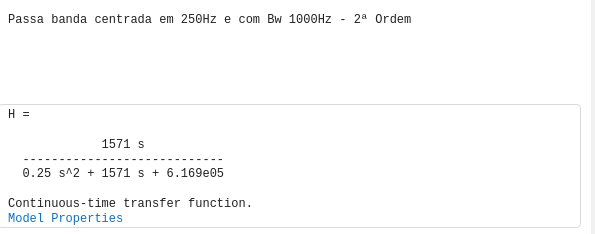

num = [0 1571 0];
den = [0.25 1571 6.169e5];

H = tf(num, den)


H =
 
            1571 s
  --------------------------
  0.25 s^2 + 1571 s + 616900
 
Continuous-time transfer function.
Model Properties


H_tustin = c2d(H, Ts, 'tustin')


H_tustin =
 
   0.0728 z^2 - 0.0728
  ----------------------
  z^2 - 1.853 z + 0.8544
 
Sample time: 2.5e-05 seconds
Discrete-time transfer function.
Model Properties



na = length(a);  % Número de coeficientes do denominador
nb = length(b);  % Número de coeficientes do numerador
N = max(na, nb); % Ordem máxima

[num, den] = tfdata(H_tustin, 'v');
b = num;
a = den;

% normalizar se a(1) ~= 1
if a(1) ~= 1
    b = b / a(1);
    a = a / a(1);
end

frequencias = [25, 250, 2500];  
duracao = 0.05;                 
t = 0:Ts:duracao;

figure;
for i = 1:length(frequencias)
    f = frequencias(i);
    x = sin(2*pi*f*t);   
    y = zeros(size(x));
    
    for n = 3:length(x)
        y(n) = -a(2)*y(n-1) - a(3)*y(n-2) + b(1)*x(n) + b(2)*x(n-1) + b(3)*x(n-2);
    end

    subplot(length(frequencias), 1, i);
    plot(t, x, 'b', 'DisplayName', 'Entrada'); hold on;
    plot(t, y, 'r', 'DisplayName', 'Saída (Filtro Tustin)');
    title(['Resposta para Senoidal de ', num2str(f), ' Hz']);
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    legend;
end

d) Rejeita-banda

2) Projetar um filtro rejeita faixa de 6 ordem com frequência central de 250 Hz, largura de banda de 1.000 Hz e frequência de amostragem de 40  kHz. Implemente esse filtro com aritmética de ponto fixo em 16 e 32 bits e verifique os resultados. Ferramentas computacionais podem ser  utilizadas para o projeto e simulação do filtro. Apresente os códigos.

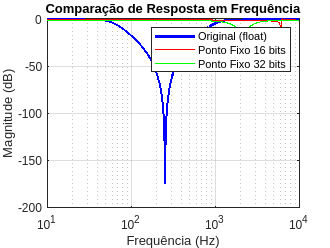

% MATLAB Code
% Generated by MATLAB(R) 24.2 and Signal Processing Toolbox 24.2.
% Generated on: 20-May-2025 19:40:09

% Butterworth Bandstop filter designed using FDESIGN.BANDSTOP.

% All frequency values are in Hz.
Fs = 40000;  % Sampling Frequency

N   = 6;     % Order
Fc1 = 59;    % First Cutoff Frequency
Fc2 = 1059;  % Second Cutoff Frequency

% Construct an FDESIGN object and call its BUTTER method.
h  = fdesign.bandstop('N,F3dB1,F3dB2', N, Fc1, Fc2, Fs);
Hd = design(h, 'butter');

f = logspace(1, 4, 1000);
[mag, phase] = freqz(Hd, f, Fs); 

figure;
semilogx(f, 20*log10(abs(mag)));
grid on;
title('Diagrama de Bode - Filtro Rejeita-Banda Butterworth');
ylabel('Magnitude (dB)');
xlabel('Frequência (Hz)');
xlim([10 10000]);

[b, a] = tf(Hd);
frac_length16 = 14;  % Parte fracionária para 16 bits
frac_length32 = 28;   % Parte fracionária para 32 bits
b_fix16 = fi(b, 1, 16, frac_length16);
a_fix16 = fi(a, 1, 16, frac_length16);
b_fix32 = fi(b, 1, 32, frac_length32);
a_fix32 = fi(a, 1, 32, frac_length32);

[mag_fix16, phase_fix16] = freqz(double(b_fix16), double(a_fix16), f, Fs);
[mag_fix32, phase_fix32] = freqz(double(b_fix32), double(a_fix32), f, Fs);

% Plotar diagrama de Bode
figure;
semilogx(f, 20*log10(abs(mag)), 'b', 'LineWidth', 2);
hold on;
semilogx(f, 20*log10(abs(mag_fix16)), 'r');
semilogx(f, 20*log10(abs(mag_fix32)), 'g');
grid on;
title('Comparação de Resposta em Frequência');
legend('Original (float)', 'Ponto Fixo 16 bits', 'Ponto Fixo 32 bits');
ylabel('Magnitude (dB)');
xlabel('Frequência (Hz)');
xlim([10 10000]);


frequencias = [25, 250, 2500];  % Frequências de interesse (Hz)
duracao = 0.05;                 % Duração do sinal em segundos
Ts = 1/Fs;                      % Período de amostragem
t = 0:Ts:duracao;               % Vetor de tempo

for i = 1:length(frequencias)
    freq = frequencias(i);
    x = sin(2*pi*freq*t);
    
    y_float = filter(b, a, x);                      
    y_fix16 = filter(double(b_fix16), double(a_fix16), x); % 16 bits
    y_fix32 = filter(double(b_fix32), double(a_fix32), x); % 32 bits
    
    subplot(length(frequencias), 1, i);
    plot(t, x, 'k--', 'LineWidth', 1.2, 'DisplayName', 'Entrada');
    hold on;
    plot(t, y_float, 'b', 'LineWidth', 1.5, 'DisplayName', 'Float');
    plot(t, y_fix16, 'r', 'LineWidth', 1.2, 'DisplayName', '16 bits');
    plot(t, y_fix32, 'g', 'LineWidth', 1.2, 'DisplayName', '32 bits');
    hold off;
    title(['Frequência = ', num2str(freq), ' Hz']);
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    legend('Location', 'best');
    grid on;
    xlim([0 duracao]);
    ylim([-1.2 1.2]);
end

Comparando a resposta em frequencia do gerado usando ponto flutuante com os de ponto fixo, notei que a frequência de centro é deslocada e a atenução do filtro diminui. 

Comparando a saida dos filtros a senoides de frequencia [25, 250, 2500], observei que o filtro projetado com ponto flutuante se comportou com esperado mas o de 16 e 32 bits esta tendendo a -infinto